## **Polynomiální regrese gradientní metodou:**

Výchozí materiál: Pattern Recognition and Machine Learning (kapitola 5).

- Cílem bylo vytvoření modelu pro vytvoření polynomiální regrese  **M**-tého řádu za pomocí gradientní metody největšího spádu, čímž vlastně nahrazujeme analytickou metodu za druh "neuronové sítě". 

- Následně bylo zapotřebí vyzkoušet různé modifikace této metody jako je využití momentu, nebo metoda ADAM.

### Příprava dat:

Testovací funkce:

% func = @(x) sin(x);                 % testovaná funkce
func = @(x) (x.^3)+(2.*x.^2)+(-5.*x)+4;
% func = @(x) (2.*x.^2)+(-5.*x)+4;
% func = @(x) (-5.*x)+4;

Vytvoříme N počet vzorků a přidáme Gaussovský šum abychom získali trénovací data pro náš regresní model. 

from = -10;   
to = 10;    

N =  20;                              % počet vzorků
x = from:((to-from)/(N-1)):to;           % vzorkovací čas
t = awgn(func(x),2);               % generátor naměřených dat     

Dále si připravíme testovací data v podobě nezkreslené funkce (bez Gaussova šumu).

x_c = from:((to-from)/((N*100)-1)):to;  % spojitý čas
t_c = func(x_c);                    % spojitý průběh

**M** odpovídá řádu polynomu, pro který budeme hledat koeficienty aproximačního polynomu.   

M = 2;                              % řád polynomu

### Výpočet a vykreslení aproximace:

První graf vykresluje ideální sínusovku modře a naměřené body zkreslené šumem černě.

figure();
plot(x,t,'kx',x_c,t_c,'b');                     % vykreslení naměřených dat
title("Vypocet a vykresleni lineárni regrese");
xlabel("x (-)");
ylabel("t (-)")
hold on;
warning('off')                                  % zákaz vypisování warning zpráv

Dále do stejného grafu vykreslíme naší spočtenou aproximaci červeně, která je spočtena funkcí **Gradient_descent. **Ta jako vstupní parametry přijmá trénovací vzorky, řád polynomu, následně požadovaná přesnost aproximace a maximální počet iterací. Místo hodnoty M je zde použit slider pro nastavení libovolného řádu polynomu nula až dvacet.

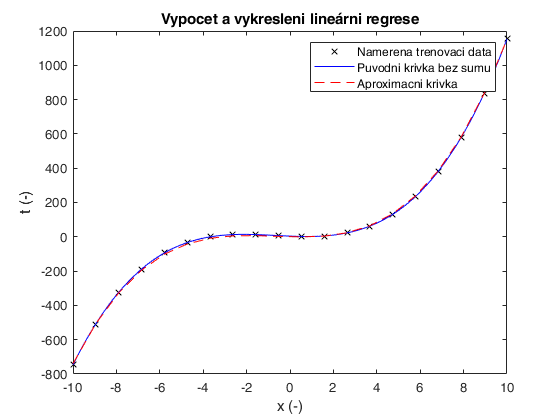

[t_w,w_aprox,~,E_w,iter] = Batch_gradient_descent(x,t,3,100,1000);   % výpočet aproximace pro M-tý řád polynomu
plot(x,t_w,'r--');                              % vykreslení proložení vypočítaným polynomem M
legend("Namerena trenovaci data","Puvodni krivka bez sumu", "Aproximacni krivka");